# MAGNO: FC, Behav, DWI ANALYSES

## DATA READ AND PREPARATION

% Read csv with all data, sent by Maddi
DT = readtable('Regressions_RawData_fa.csv','VariableNamingRule',"modify");
% Make subID categorical
DT.subID=categorical(DT.subID);
% Create new variable measurements, for now we only have FA but I will add the
% rest of the measures she sent me in excel files
DT.meas=categorical(repmat({'FA'},[height(DT),1]));
% Create array element instead of using so many columns
DT.val=repmat(zeros(1,100),[height(DT),1]);
for na=1:height(DT);DT.val(na,:)=DT{na,contains(DT.Properties.VariableNames,'vals_')};end
% Obtain the mean of the tract
DT.meanval=mean(DT.val,2);
% Remove the vals_x columns from the dataset
% Do not, we will use it later in a lm fit
% DT=DT(:,~contains(DT.Properties.VariableNames,'vals_'));

% Create the epochs
nEpoch = 5;
epochInd=[1:100/nEpoch:100,101];
for pp=1:nEpoch
    DT.(['epoch_' num2str(pp)])=mean(DT.val(:,(epochInd(pp):epochInd(pp+1)-1)),2);
end

% Create the var name lists for our analyses
behavs = {'RW_CS','RW_PS'};
FCs    = DT.Properties.VariableNames(contains(DT.Properties.VariableNames,'FC_'));

## PLOT FOR CHECKING RAW DATA

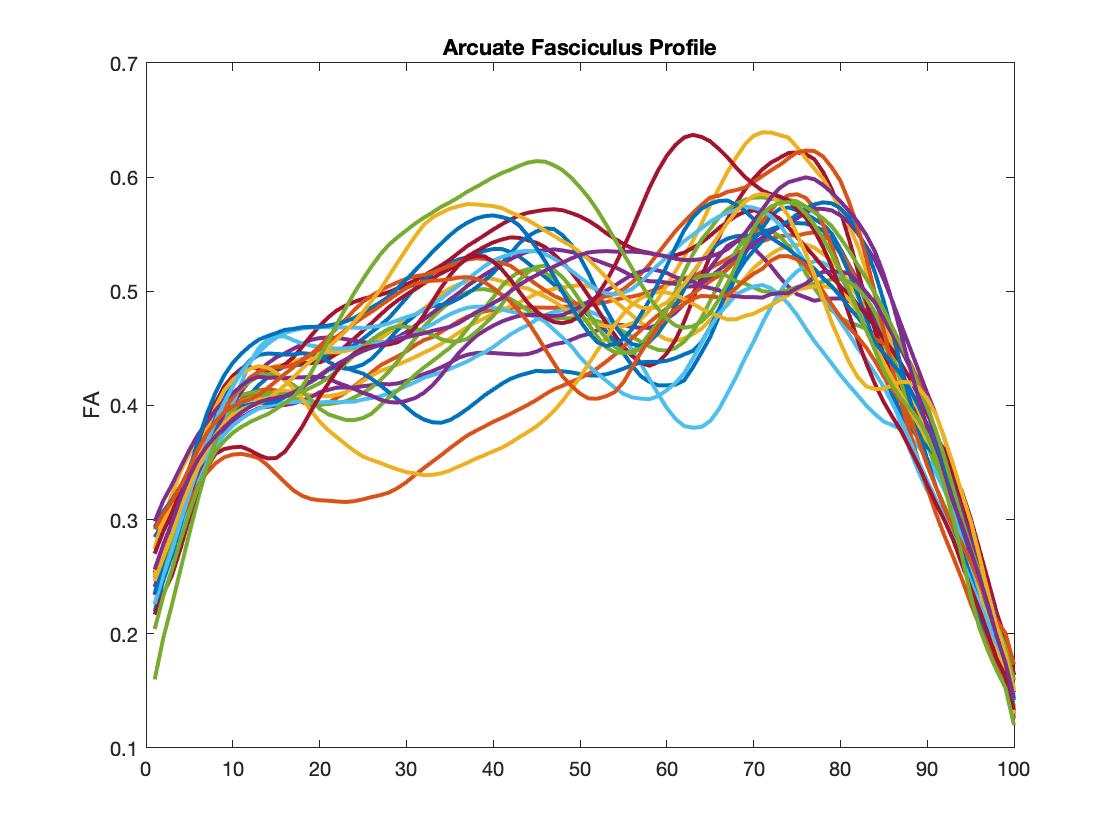

% PLOT DWI Profiles
Meas="FA";
figure(1);plot(DT.val(DT.meas==Meas,:)');ylabel(Meas);title('Arcuate Fasciculus Profile')

We already observe that the values on the borders are basically meaningless, as expected. We will use the mean for analyses, and separated in epochs as well. We can get fancier with epoch selection, but it is hard to justify. 

I am not happy either witht the inhomogeneity in the shapes. The basic shape is:

- Low at the extremes

- A bump of lower values in the middle (due to crossing fibers). We will see how our correlation results are worse in that bump. 

- The problem is that all subjects have that bump, but it is not exactly located in the same index in all subjects:

-     TODO: I would try one thing for homogeneity: select the lowest point of the bump in all subjects, and discard 5-10 points to each side. Then select the values of the tract and average for 20-30 points, and use that value in the correlations. 

-         I tested it at the end already. 

Scatterplot of RW_CS and RW_PS with the DWI mean values. It looks that there is no relation in RW_PS. But then later on we see most of the results in RW_PS, and this is due to the relation between DWI and the FC values. 

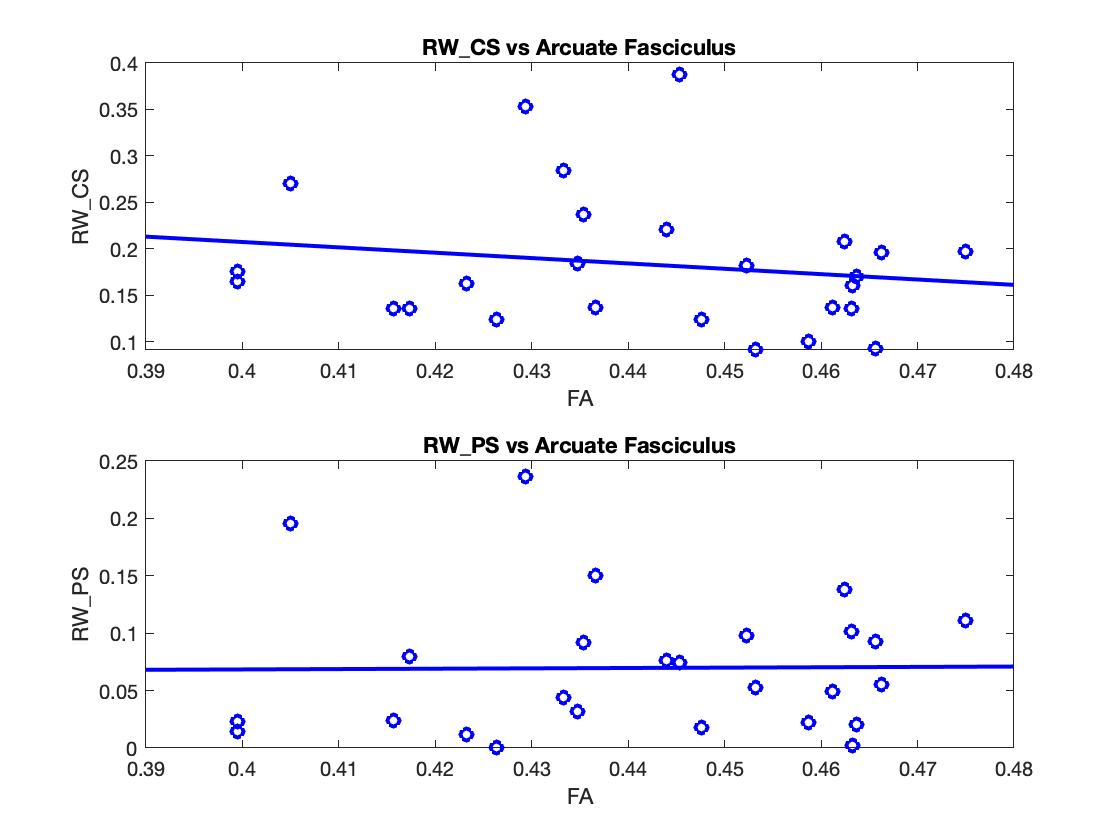


% Plot BEHAV vs DWI means
figure(2);
subplot(2,1,1);
    plot(DT.meanval(DT.meas==Meas), DT.RW_CS(DT.meas==Meas),'bo');lsline(gca);
    xlabel(Meas);ylabel("RW\_CS");title("RW\_CS vs Arcuate Fasciculus")
subplot(2,1,2);
    plot(DT.meanval(DT.meas==Meas), DT.RW_PS(DT.meas==Meas),'bo');lsline(gca);
    xlabel(Meas);ylabel("RW\_PS");title("RW\_PS vs Arcuate Fasciculus")


% Plot BEHAV vs FC: this is already in Maddi's poster



## ANALYSES

Two levels of analyses, if the FC and Behav score p is below 0.005, then add the Arcuate Fasciculus and check if the variance explained  improves or not. 

NOTE: There is an interaction between FC score and the Arcuate (the models are better with the interaction term...). Check the model details below. 

LMs = {};
ii=1;
for nb=1:length(behavs)
    for nf=1:length(FCs)
        LM=fitlm(DT,[behavs{nb} ' ~ ' FCs{nf}]);
        p=LM.coefTest;
        AR2=LM.Rsquared.Adjusted;
        if p < 0.005
            % fprintf('\n%s ~ (%i)%s, AR2: %.2g (p:%.2g) \n',behavs{nb},nf,FCs{nf},AR2,p)
            % Add tract (with interaction term)
            LM2=fitlm(DT,[behavs{nb} ' ~ ' FCs{nf} ' * meanval']);
            p2=LM2.coefTest;
            AR22=LM2.Rsquared.Adjusted;
            if AR22 >= AR2
                fprintf('\n%s ~ (%i)%s, AR2: %.2g (p:%.2g) \n',behavs{nb},nf,FCs{nf},AR2,p)
                fprintf('       AR22: %.2g (p:%.2g) \n',AR22,p2);
                LMs{ii} = LM2;
                ii=ii+1;
            end
        end
    end
end

RW_PS ~ (5)FC_parvoW_mOTSOpercularis, AR2: 0.36 (p:0.00071) 


       AR22: 0.42 (p:0.0018) 


RW_PS ~ (13)FC_parvoW_mOTSOrbitalis, AR2: 0.33 (p:0.0013) 


       AR22: 0.51 (p:0.00028) 


RW_PS ~ (21)FC_parvoW_mOTSTriangularis, AR2: 0.34 (p:0.001) 


       AR22: 0.55 (p:0.00013) 


Visualize the details of just the surviving models:


% for ii=1:length(LMs); disp(LMs{ii}); end 
disp(LMs{1})

Linear regression model:
    RW_PS ~ 1 + FC_parvoW_mOTSOpercularis*meanval

Estimated Coefficients:
                                         Estimate      SE        tStat      pValue 
                                         ________    _______    _______    ________

    (Intercept)                            0.5931    0.25378      2.337    0.028945
    FC_parvoW_mOTSOpercularis            -0.61566    0.33257    -1.8512    0.077606
    meanval                               -1.1468    0.56695    -2.0227    0.055422
    FC_parvoW_mOTSOpercularis:meanval      1.2636    0.74557     1.6948     0.10423


Number of observations: 26, Error degrees of freedom: 22
Root Mean Squared Error: 0.0457
R-squared: 0.487,  Adjusted R-Squared: 0.417
F-statistic vs. constant model: 6.97, p-value = 0.00181

disp(LMs{2})

Linear regression model:
    RW_PS ~ 1 + FC_parvoW_mOTSOrbitalis*meanval

Estimated Coefficients:
                                       Estimate      SE        tStat      pValue  
                                       ________    _______    _______    _________

    (Intercept)                         0.76799    0.22548      3.406    0.0025346
    FC_parvoW_mOTSOrbitalis            -0.94761    0.31393    -3.0186    0.0063167
    meanval                             -1.5231    0.50278    -3.0293    0.0061611
    FC_parvoW_mOTSOrbitalis:meanval      1.9916    0.70752      2.815     0.010086


Number of observations: 26, Error degrees of freedom: 22
Root Mean Squared Error: 0.0419
R-squared: 0.57,  Adjusted R-Squared: 0.512
F-statistic vs. constant model: 9.73, p-value = 0.000277


disp(LMs{3})

Linear regression model:
    RW_PS ~ 1 + FC_parvoW_mOTSTriangularis*meanval

Estimated Coefficients:
                                          Estimate      SE        tStat      pValue  
                                          ________    _______    _______    _________

    (Intercept)                           0.78598     0.21653     3.6298     0.001481
    FC_parvoW_mOTSTriangularis            -1.0134     0.30539    -3.3184    0.0031229
    meanval                                -1.564     0.48289    -3.2387    0.0037713
    FC_parvoW_mOTSTriangularis:meanval     2.1372     0.68698      3.111    0.0050928


Number of observations: 26, Error degrees of freedom: 22
Root Mean Squared Error: 0.0404
R-squared: 0.601,  Adjusted R-Squared: 0.546
F-statistic vs. constant model: 11, p-valu

Interpretation: 

- There is functional connectivitiy between RW_PS results and the parvoW functional connectivity between mOTS and the three components of IFG. 

- The mean FA value of the Arcuate Fasciculus, the tract that connects both functional regions, is contributing significantly to explain the behavioural result. 

## ANALYSIS WITH THE WHOLE TRACT PROFILE

We should have less expectatives, because the shape is different and maybe the same part of the tract will not correspond between subjects...

I am plotting the diffrence in the variance explained, only in the three models above. 

We want the regions with positive values, which is Adjusted Variance Explained in the DWI model - Adjusted Variance Explained without DWI. 

pProfiles = {};
ii=0;
for nb=1:length(behavs)
    for nf=1:length(FCs)
        LM=fitlm(DT,[behavs{nb} ' ~ ' FCs{nf}]);
        p=LM.coefTest;
        AR2=LM.Rsquared.Adjusted;
        if p < 0.005
            % fprintf('\n%s ~ (%i)%s, AR2: %.2g (p:%.2g) \n',behavs{nb},nf,FCs{nf},AR2,p)
            % Add tract (with interaction term)
            % But now we will add every point in the profile
            % For now, do it only in the profiles that survive the mean
            LM2=fitlm(DT,[behavs{nb} ' ~ ' FCs{nf} ' * meanval']);
            p2=LM2.coefTest;
            AR22=LM2.Rsquared.Adjusted;
            if AR22 >= AR2
                ii=ii+1;
                ps = zeros(1,100);
                for kk=1:100
                   LMtmp  = fitlm(DT,[behavs{nb} ' ~ ' FCs{nf} ' * vals_' int2str(kk)]);
                   % ps(kk) = LMtmp.coefTest;
                   % Instead of the p of the model, check the difference in
                   % variance explained
                   ps(kk) = LMtmp.Rsquared.Adjusted - LM.Rsquared.Adjusted;
                end
                pProfiles{ii} = ps;
            end
        end
    end
end



## Plot the profiles:

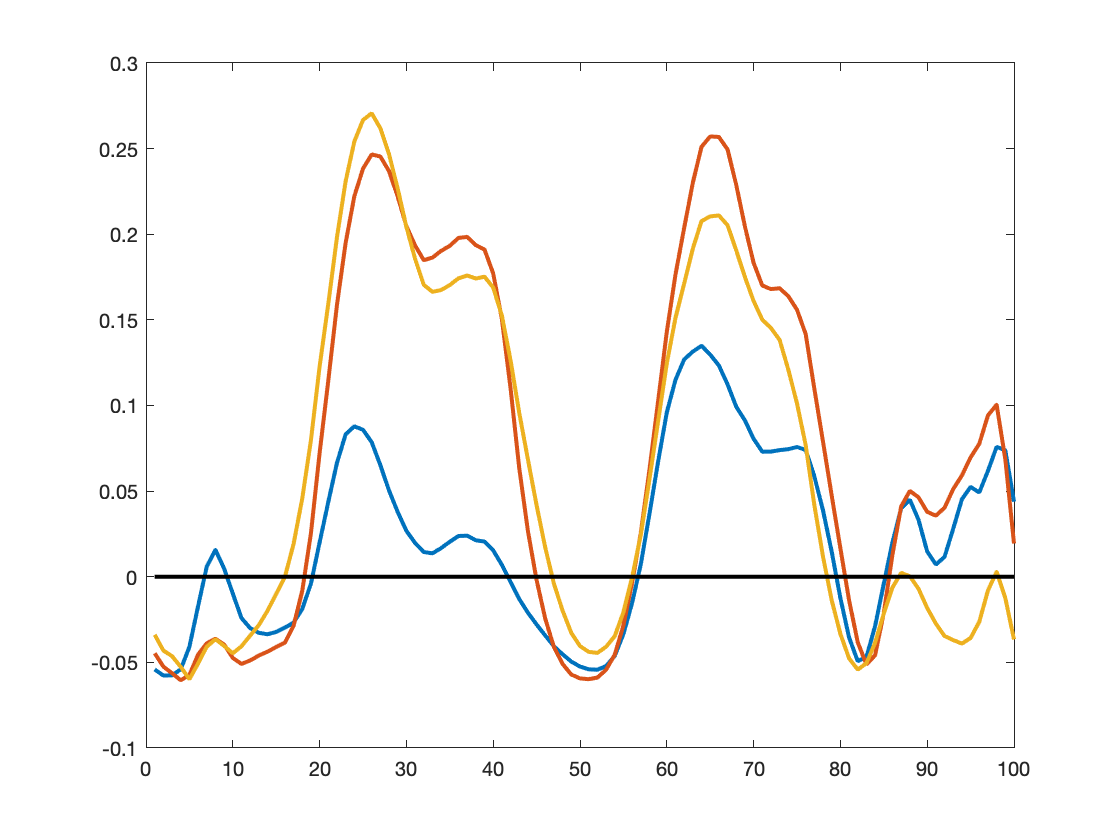

close all;
for ii=1:length(pProfiles)
    plot(pProfiles{ii});hold on
end 
plot(1:100,zeros(100),'k-')

We see how the effect is mostly concentrated in the 20-40 and 60-80 epoch. We actually should not care about the first/last 10-15 points because of the methods. 

Now I will do analyses in those epochs

## EPOCH ANALYSES

pProfiles = {};
ii=0;
for nb=1:length(behavs)
    for nf=1:length(FCs)
        LM=fitlm(DT,[behavs{nb} ' ~ ' FCs{nf}]);
        p=LM.coefTest;
        AR2=LM.Rsquared.Adjusted;
        if p < 0.005
            % fprintf('\n%s ~ (%i)%s, AR2: %.2g (p:%.2g) \n',behavs{nb},nf,FCs{nf},AR2,p)
            % Add tract (with interaction term)
            % But now we will add every point in the profile
            % For now, do it only in the profiles that survive the mean
            LM2=fitlm(DT,[behavs{nb} ' ~ ' FCs{nf} ' * meanval']);
            p2=LM2.coefTest;
            AR22=LM2.Rsquared.Adjusted;
            if AR22 >= AR2
                ii=ii+1;
                ps = zeros(1,nEpoch);
                for kk=1:nEpoch
                   LMtmp  = fitlm(DT,[behavs{nb} ' ~ ' FCs{nf} ' * epoch_' int2str(kk)]);
                   % ps(kk) = LMtmp.coefTest;
                   % Instead of the p of the model, check the difference in
                   % variance explained
                   ps(kk) = LMtmp.Rsquared.Adjusted - LM.Rsquared.Adjusted;
                end
                pProfiles{ii} = ps;
            end
        end
    end
end

## Plot the Adjusted R2 difference in every epoch

We are only interested in the positive values, as before. 

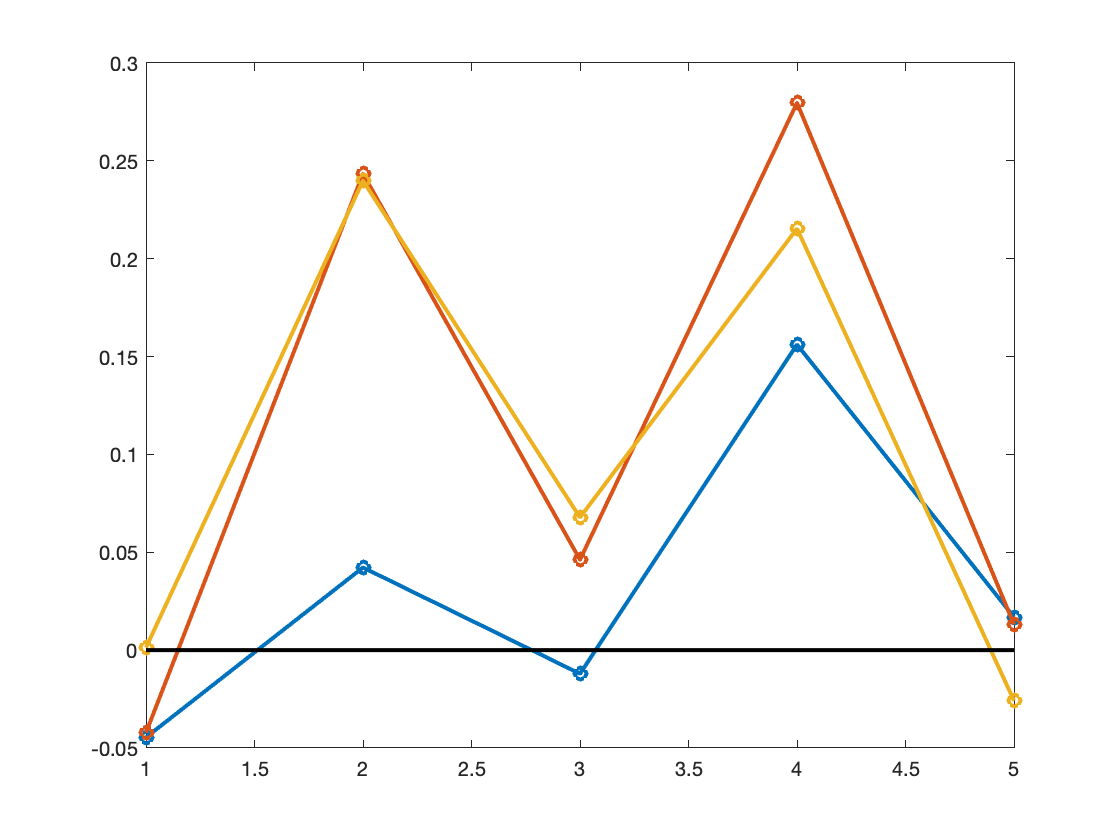

close all; 
for ii=1:length(pProfiles)
    plot(pProfiles{ii},'o-');hold on
end 
plot(1:5,zeros(5),'k-')

All are significant in the core of the tract (except one...). We are basically seing the same thing as in the profile analyses. 

I will work on 2nd and 4th epochs, and look what is different in the middle of the tract. More crossing fibers... whatever, I will look at the literature for the manuscript. 

## Check linear models again in the epochs we've seen that are working best (2 and 4)

Now show all the correlations that are below 0.05 for RW_ and FC.

Then, check if the DWI improves the Adjusted Variance Explained. 

If it is the case, print the improvement below marking it with    >>  :

- For RW_CS there are no surviving models, as it was before. 

for nb=1:length(behavs)
    fprintf('\n\n>>>>>>>>>>>>> %s <<<<<<<<<<<<<<< \n',behavs{nb})
    for nf=1:length(FCs)
        LM=fitlm(DT,[behavs{nb} ' ~ ' FCs{nf}]);
        p=LM.coefTest;
        AR2=LM.Rsquared.Adjusted;
        if p < 0.05
            fprintf('\n%s ~ (%i)%s, AR2: %.2g (p:%.2g) \n',behavs{nb},nf,FCs{nf},AR2,p)
            % Add tract (with interaction term)
            % But now we will add every point in the profile
            % For now, do it only in the profiles that survive the mean
            
            % Calculate epoch 2
            LM2=fitlm(DT,[behavs{nb} ' ~ ' FCs{nf} ' * epoch_2']);
            p2=LM2.coefTest;
            AR22=LM2.Rsquared.Adjusted;
            % Calculate epoch 4
            LM4=fitlm(DT,[behavs{nb} ' ~ ' FCs{nf} ' * epoch_4']);
            p4=LM4.coefTest;
            AR24=LM4.Rsquared.Adjusted;
            if AR22 >= AR2
                fprintf('   >> EPOCH_2: AR2: %.2g (p:%.2g) \n',AR22,p2)
            end
            if AR24 >= AR2
                fprintf('   >> EPOCH_4: AR2: %.2g (p:%.2g) \n',AR24,p4)
            end
        end
    end
end



>>>>>>>>>>>>> RW_CS <<<<<<<<<<<<<<< 


RW_CS ~ (1)FC_magnoW_mOTSOpercularis, AR2: 0.15 (p:0.04) 

RW_CS ~ (4)FC_magnoI_pOTSOpercularis, AR2: 0.2 (p:0.012) 

RW_CS ~ (12)FC_magnoI_pOTSOrbitalis, AR2: 0.29 (p:0.0029) 

RW_CS ~ (20)FC_magnoI_pOTSTriangularis, AR2: 0.31 (p:0.0019) 




>>>>>>>>>>>>> RW_PS <<<<<<<<<<<<<<< 


RW_PS ~ (5)FC_parvoW_mOTSOpercularis, AR2: 0.36 (p:0.00071) 


   >> EPOCH_2: AR2: 0.4 (p:0.0024) 


   >> EPOCH_4: AR2: 0.52 (p:0.00025) 


RW_PS ~ (6)FC_parvoW_pOTSOpercularis, AR2: 0.14 (p:0.034) 


   >> EPOCH_2: AR2: 0.2 (p:0.046) 


   >> EPOCH_4: AR2: 0.26 (p:0.022) 


RW_PS ~ (7)FC_parvoI_mOTSOpercularis, AR2: 0.26 (p:0.0049) 

RW_PS ~ (13)FC_parvoW_mOTSOrbitalis, AR2: 0.33 (p:0.0013) 


   >> EPOCH_2: AR2: 0.57 (p:6.5e-05) 


   >> EPOCH_4: AR2: 0.61 (p:2.5e-05) 


RW_PS ~ (21)FC_parvoW_mOTSTriangularis, AR2: 0.34 (p:0.001) 


   >> EPOCH_2: AR2: 0.58 (p:5.4e-05) 


   >> EPOCH_4: AR2: 0.56 (p:9.9e-05) 


## Do the same thing, but do not restrict to the existing results, create the full model with DWI from the beginning

We see that we have more models now that are with p below 0.05. The thing is that we already now that the without DWI the results will be better, we need to look at the LM and decide. I would just show the main 3 results only...

for nb=1:length(behavs)
    fprintf('\n\n>>>>>>>>>>>>> %s <<<<<<<<<<<<<<< \n',behavs{nb})
    for nf=1:length(FCs)
        % Calculate epoch 2
        LM2=fitlm(DT,[behavs{nb} ' ~ ' FCs{nf} ' * epoch_2']);
        p2=LM2.coefTest;
        AR22=LM2.Rsquared.Adjusted;
        % Calculate epoch 4
        LM4=fitlm(DT,[behavs{nb} ' ~ ' FCs{nf} ' * epoch_4']);
        p4=LM4.coefTest;
        AR24=LM4.Rsquared.Adjusted;
        if ~(p4 > 0.05 && p2 > 0.05)
            fprintf('\n%s ~ (%i)%s: \n',behavs{nb},nf,FCs{nf})
        end
        if p2 <= 0.05
            fprintf('   >> EPOCH_2: AR2: %.2g (p:%.2g) \n',AR22,p2)
        end
        if p4 <= 0.05
            fprintf('   >> EPOCH_4: AR2: %.2g (p:%.2g) \n',AR24,p4)
        end
        
   end
end



>>>>>>>>>>>>> RW_CS <<<<<<<<<<<<<<< 


RW_CS ~ (12)FC_magnoI_pOTSOrbitalis: 


   >> EPOCH_2: AR2: 0.22 (p:0.035) 


   >> EPOCH_4: AR2: 0.26 (p:0.023) 


RW_CS ~ (20)FC_magnoI_pOTSTriangularis: 


   >> EPOCH_2: AR2: 0.26 (p:0.023) 


   >> EPOCH_4: AR2: 0.27 (p:0.02) 




>>>>>>>>>>>>> RW_PS <<<<<<<<<<<<<<< 


RW_PS ~ (4)FC_magnoI_pOTSOpercularis: 


   >> EPOCH_4: AR2: 0.2 (p:0.048) 


RW_PS ~ (5)FC_parvoW_mOTSOpercularis: 


   >> EPOCH_2: AR2: 0.4 (p:0.0024) 


   >> EPOCH_4: AR2: 0.52 (p:0.00025) 


RW_PS ~ (6)FC_parvoW_pOTSOpercularis: 


   >> EPOCH_2: AR2: 0.2 (p:0.046) 


   >> EPOCH_4: AR2: 0.26 (p:0.022) 


RW_PS ~ (7)FC_parvoI_mOTSOpercularis: 


   >> EPOCH_2: AR2: 0.24 (p:0.029) 


   >> EPOCH_4: AR2: 0.24 (p:0.03) 


RW_PS ~ (12)FC_magnoI_pOTSOrbitalis: 


   >> EPOCH_4: AR2: 0.2 (p:0.046) 


RW_PS ~ (13)FC_parvoW_mOTSOrbitalis: 


   >> EPOCH_2: AR2: 0.57 (p:6.5e-05) 


   >> EPOCH_4: AR2: 0.61 (p:2.5e-05) 


RW_PS ~ (14)FC_parvoW_pOTSOrbitalis: 


   >> EPOCH_2: AR2: 0.4 (p:0.0024) 


RW_PS ~ (21)FC_parvoW_mOTSTriangularis: 


   >> EPOCH_2: AR2: 0.58 (p:5.4e-05) 


   >> EPOCH_4: AR2: 0.56 (p:9.9e-05) 


RW_PS ~ (22)FC_parvoW_pOTSTriangularis: 


   >> EPOCH_2: AR2: 0.38 (p:0.0036) 


## Same thing using the mean of the whole profile

Well, some changes... but they would not resist the multiple comparisons or cross validation...

for nb=1:length(behavs)
    fprintf('\n\n>>>>>>>>>>>>> %s <<<<<<<<<<<<<<< \n',behavs{nb})
    for nf=1:length(FCs)
        % Calculate epoch 2
        LM2=fitlm(DT,[behavs{nb} ' ~ ' FCs{nf} ' * meanval']);
        p2=LM2.coefTest;
        AR22=LM2.Rsquared.Adjusted;
        
        if p2 <= 0.05
            fprintf('\n%s ~ (%i)%s: \n',behavs{nb},nf,FCs{nf})
            fprintf('   >> MEAN: AR2: %.2g (p:%.2g) \n',AR22,p2)
        end 
   end
end



>>>>>>>>>>>>> RW_CS <<<<<<<<<<<<<<< 


RW_CS ~ (6)FC_parvoW_pOTSOpercularis: 


   >> MEAN: AR2: 0.23 (p:0.031) 


RW_CS ~ (12)FC_magnoI_pOTSOrbitalis: 


   >> MEAN: AR2: 0.25 (p:0.024) 


RW_CS ~ (20)FC_magnoI_pOTSTriangularis: 


   >> MEAN: AR2: 0.28 (p:0.016) 




>>>>>>>>>>>>> RW_PS <<<<<<<<<<<<<<< 


RW_PS ~ (5)FC_parvoW_mOTSOpercularis: 


   >> MEAN: AR2: 0.42 (p:0.0018) 


RW_PS ~ (6)FC_parvoW_pOTSOpercularis: 


   >> MEAN: AR2: 0.28 (p:0.017) 


RW_PS ~ (7)FC_parvoI_mOTSOpercularis: 


   >> MEAN: AR2: 0.21 (p:0.042) 


RW_PS ~ (13)FC_parvoW_mOTSOrbitalis: 


   >> MEAN: AR2: 0.51 (p:0.00028) 


RW_PS ~ (14)FC_parvoW_pOTSOrbitalis: 


   >> MEAN: AR2: 0.38 (p:0.0033) 


RW_PS ~ (21)FC_parvoW_mOTSTriangularis: 


   >> MEAN: AR2: 0.55 (p:0.00013) 


RW_PS ~ (22)FC_parvoW_pOTSTriangularis: 


   >> MEAN: AR2: 0.33 (p:0.0075) 
